%parameters needed for bandpass butter function
Omega_passband_start = 5*pi/24;
Omega_passband_end = 11*pi/24;
Fs = 1000; % Sampling frequency (not specified in problem)
v = [Omega_passband_start/(Fs/2), Omega_passband_end/(Fs/2)]

v =     0.0013    0.0029


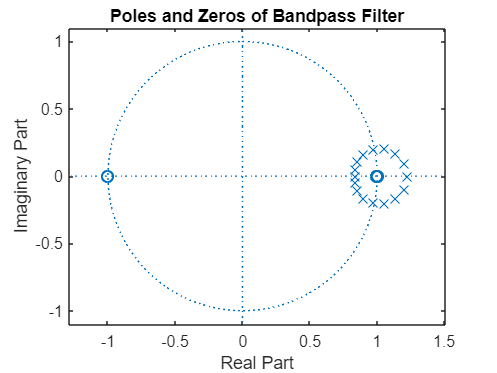


% Eighth-order digital bandpass filter
[b_bandpass, a_bandpass] = butter(8, v, 'bandpass');
figure;
zplane(b_bandpass, a_bandpass);
title('Poles and Zeros of Bandpass Filter');

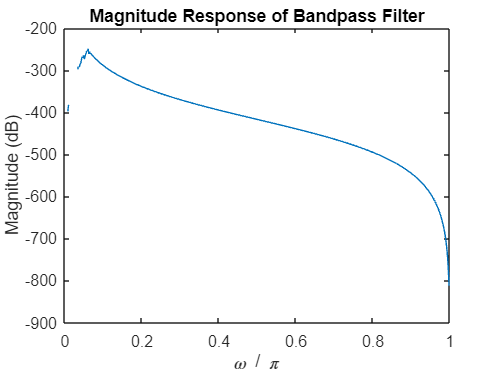


[h,w] = freqz(b_bandpass,a_bandpass);
dB = mag2db(abs(h)); %dB = 20 log10(|h|).
plot(w/pi,dB)
xlabel('\omega / \pi')
ylabel('Magnitude (dB)')
title('Magnitude Response of Bandpass Filter');